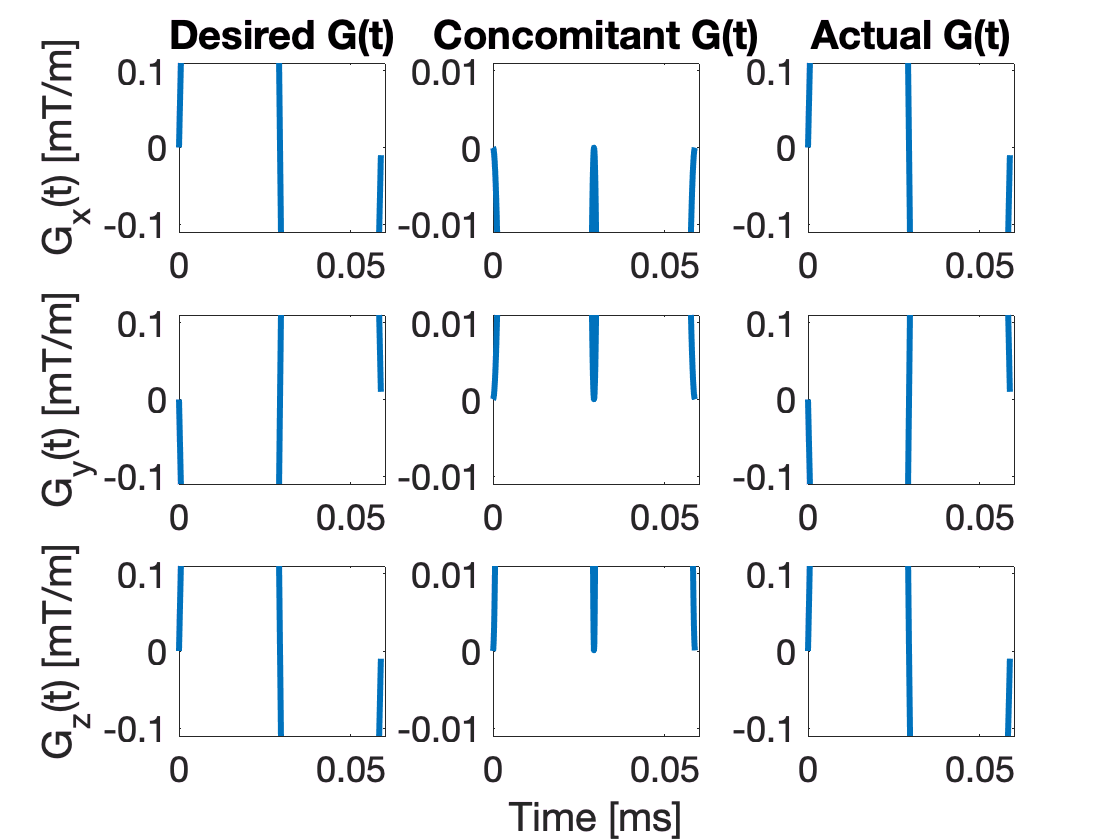

%% This script demonstrates the impact of Maxwell (concomitant) gradient 
%  fields for a bipolar diffusion gradient 
%
% Code Author: Matt Middione and Daniel Ennis

% Variables
matrix = 256;               % Image matrix size, unitless
fov = 0.256;                % Field-of-view [m]
alpha = 15;                 % Gradient echo flip angle [degrees]
TR=3000e-3;                 % Repetition time [s]
TE=  50e-3;                 % Echo time [s]
B0=0.5;                     % Field strength [T]
gMax=450e-3;                % Maximum gradient amplitude [T/m]
sMax=200;                   % Maximum gradient slewrate [T/m/s]
dt=100e-6;                  % Time-step [s]
dG=sMax*dt;                 % Maximum gradient increment per time step [T/m]
deltaDiff=12.8e-3;          % Diffusion gradient lobe duration [s]
G_dir=[1 -1 1];             % Gradient direction vector
pos=[-fov/2 fov/2 fov/2];   % Distance from isocenter along (x,y,z) [m]
X_pos=-(fov/2):(fov/matrix):(fov/2);
Y_pos=-(fov/2):(fov/matrix):(fov/2);
[Y,X]=ndgrid(X_pos,Y_pos);

%% Generate a bipolar diffusion gradient
G_rise=0:dG:gMax;
G_flat=gMax*ones(1,13*dG*1e3);
G_trans=gMax:-2*dG:-gMax;
G_fall=-gMax:dG:0;
G=[G_rise G_flat G_trans -G_flat G_fall]; % Concatenate the gradient events
tvec=0:dt:dt*(length(G)-1);               % Time vector [s]

% Calculate the b-value
gamma=267.52e6;     % Gyromagnetic ratio [rad/s/T]
b_val=2*gamma^2.*(gMax.*G_dir).^2.*((deltaDiff)^3/3)*1e-6; % [s/mm^2]

%% Calculate the Concomitant gradient fields for the given parameters
G_0=G.*G_dir';            % Target gradients
GCt=zeros(3,3,length(G)); % Initialize concomitant gradient matrix
dGC=zeros(3,length(G));   % Initialize concomitant gradient waveforms
for t=1:length(G)
    % Concomitant gradient matrix
    GCt(:,:,t)=(1/(4*B0)).*[G_0(3,t)^2            0                     -2*G_0(1,t)*G_0(3,t); 
                            0                     G_0(3,t)^2            -2*G_0(2,t)*G_0(3,t); 
                            -2*G_0(1,t)*G_0(3,t)  -2*G_0(2,t)*G_0(3,t)  4*G_0(1,t)^2 + 4*G_0(2,t)^2];
    % Concomitant gradient waveform offset (delta)
    dGC(:,t)=GCt(:,:,t)*pos';      
end

% Comcomitant corrupted gradient waveforms (Target + delta Concominant)
G_C=G_0+dGC;

%% Compare the target and concomitant corrupted gradient waveforms
set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',18);
f=figure; hold on; xlabel('Time [s]'); ylabel('G(t) [mT/m]');

% X-axis
subplot(3,3,1); plot(tvec,G_0(1,:)); axis([0 0.06 -0.110 0.110]); title('Desired G(t)'); ylabel('G_{x}(t) [mT/m]');
subplot(3,3,2); plot(tvec,dGC(1,:)); axis([0 0.06 -0.011 0.011]); title('Concomitant G(t)');
subplot(3,3,3); plot(tvec,G_C(1,:)); axis([0 0.06 -0.110 0.110]); title('Actual G(t)'); 

% Y-axis
subplot(3,3,4); plot(tvec,G_0(2,:)); axis([0 0.06 -0.110 0.110]); ylabel('G_{y}(t) [mT/m]');
subplot(3,3,5); plot(tvec,dGC(2,:)); axis([0 0.06 -0.011 0.011]);
subplot(3,3,6); plot(tvec,G_C(2,:)); axis([0 0.06 -0.110 0.110]); 

% Z-axis
subplot(3,3,7); plot(tvec,G_0(3,:)); axis([0 0.06 -0.110 0.110]); ylabel('G_{z}(t) [mT/m]');
subplot(3,3,8); plot(tvec,dGC(3,:)); axis([0 0.06 -0.011 0.011]); xlabel('Time [ms]');
subplot(3,3,9); plot(tvec,G_C(3,:)); axis([0 0.06 -0.110 0.110]); 

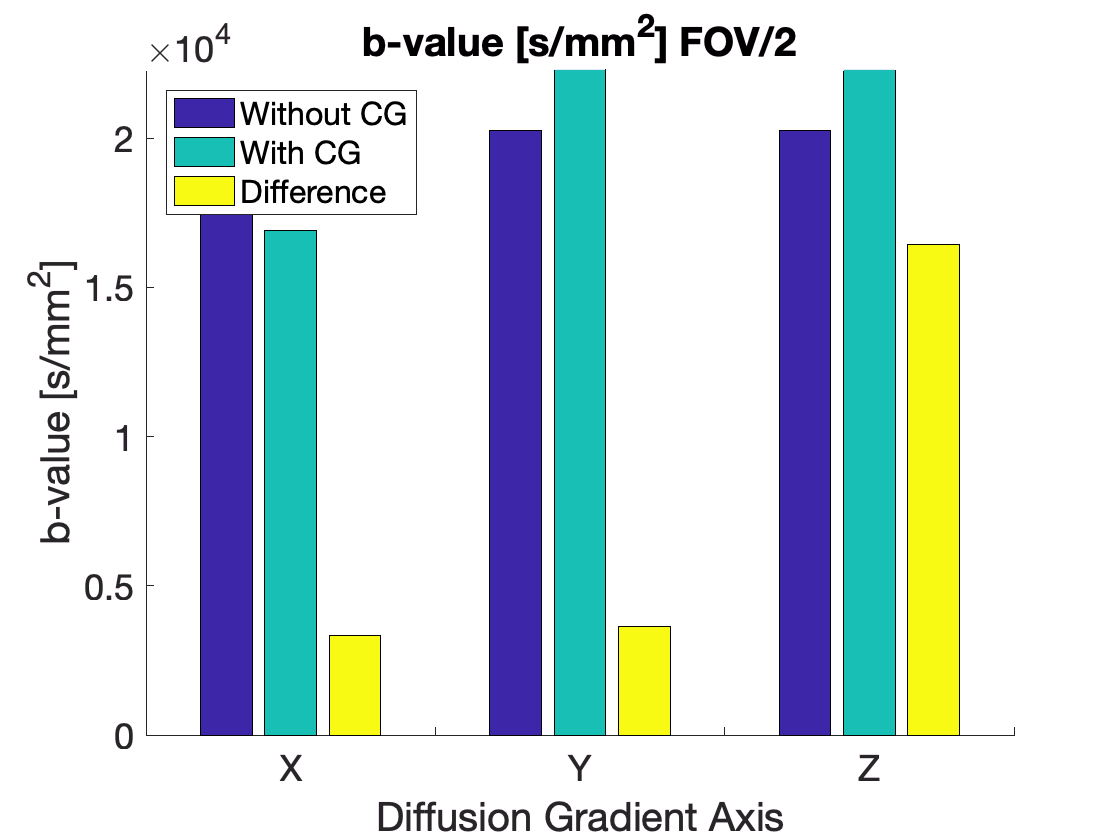


%% Calculate the new b-values for each axis due to concomitant fields
bXcg=2*gamma^2*(max(G_C(1,:)))^2*((deltaDiff)^3/3)*1e-6;
bYcg=2*gamma^2*(max(G_C(2,:)))^2*((deltaDiff)^3/3)*1e-6;
bZcg=2*gamma^2*(max(G_C(3,:)))^2*((deltaDiff)^3/3)*1e-6;

f=figure; hold on;
  y = [b_val(1,1) bXcg abs(bXcg-b_val(1,1)); b_val(1,2) bYcg abs(bYcg-b_val(1,2)); b_val(1,3) bZcg abs(bZcg-b_val(1,3))];
  bar(y); axis([0.5          3.5            0         1.1*max(b_val)]);
  xlabel('Diffusion Gradient Axis'); ylabel('b-value [s/mm^{2}]');
  legend('Without CG','With CG','Difference','Location','NorthWest');
  xticklabels({'' 'X' '' 'Y' '' 'Z'}); title('b-value [s/mm^2] FOV/2');